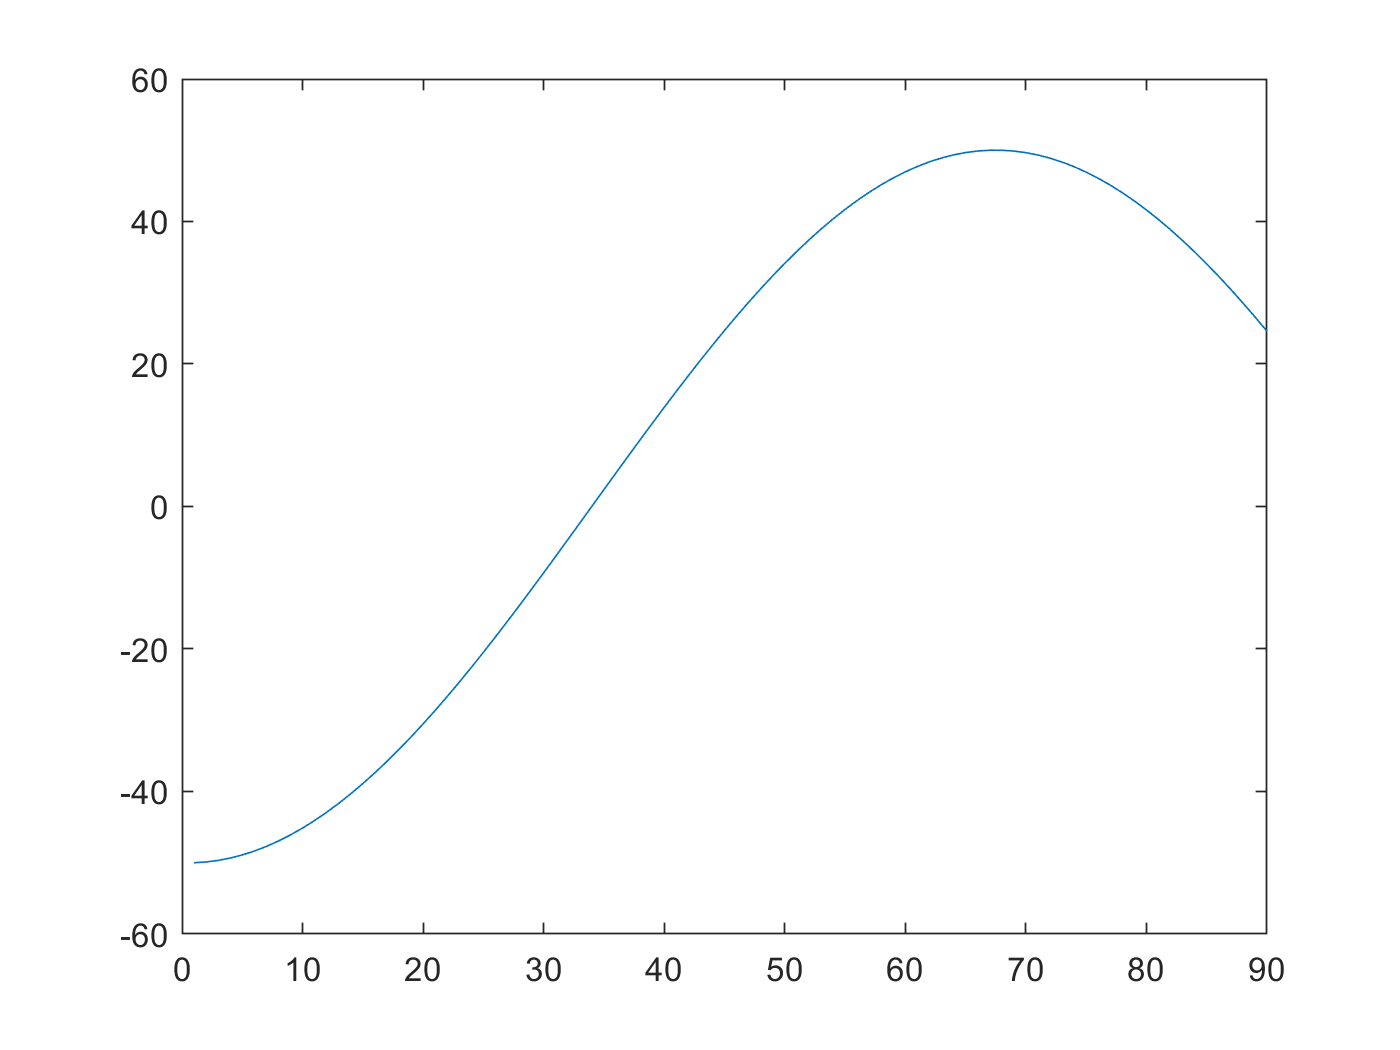

x_size = 90;

init_x = -50;
goal_x = 0;
kp = 0.0022;
speed = 0;

steps = 610;
x = zeros(1,steps+1);
x(1) = init_x;

for i = 1:steps
    x_now = x(i);
    error = goal_x - x_now;
    power = kp * error;
    speed = speed + power;
    x(i+1) = x_now + speed;
end

plot(1:steps+1, x);
xlim([0 x_size])

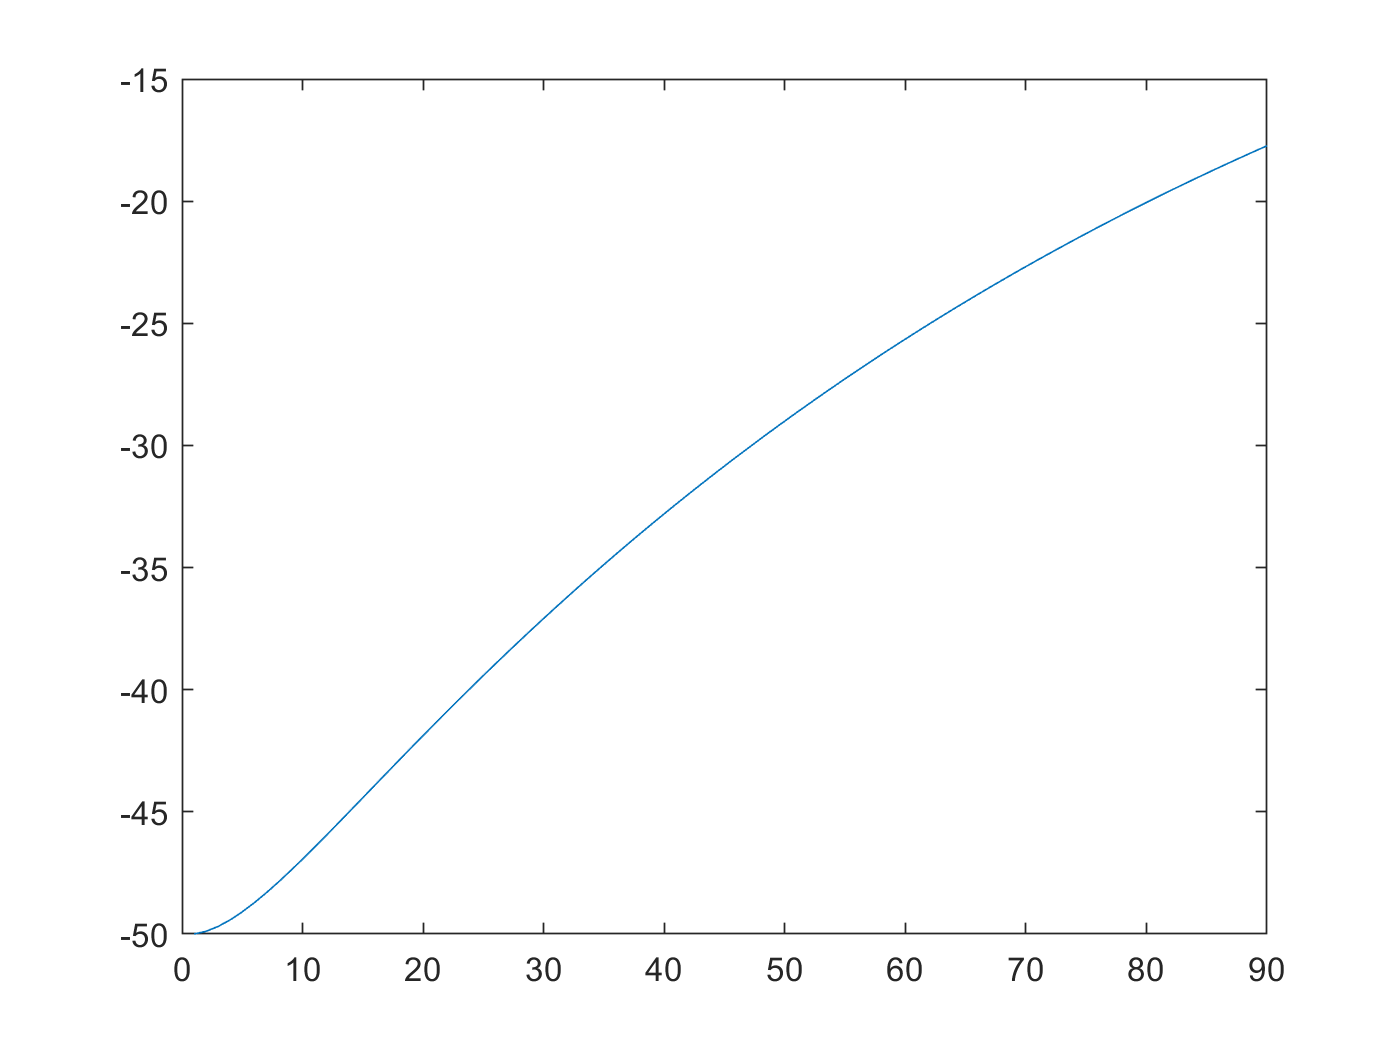


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

%speed_limit = 10;
mu_x = 0.19;
steps = 670;

x = zeros(1,steps+1);
x(1) = init_x;
speed=0;

for i = 1:steps
    x_now = x(i);
    error = goal_x - x_now;
    power = kp * error;
    actual_power = power - speed*mu_x;
    %speed = min(speed + power, speed);
    speed = speed + actual_power;
    x(i+1) = x_now + speed;
end

plot(1:steps+1, x);
xlim([0 x_size])

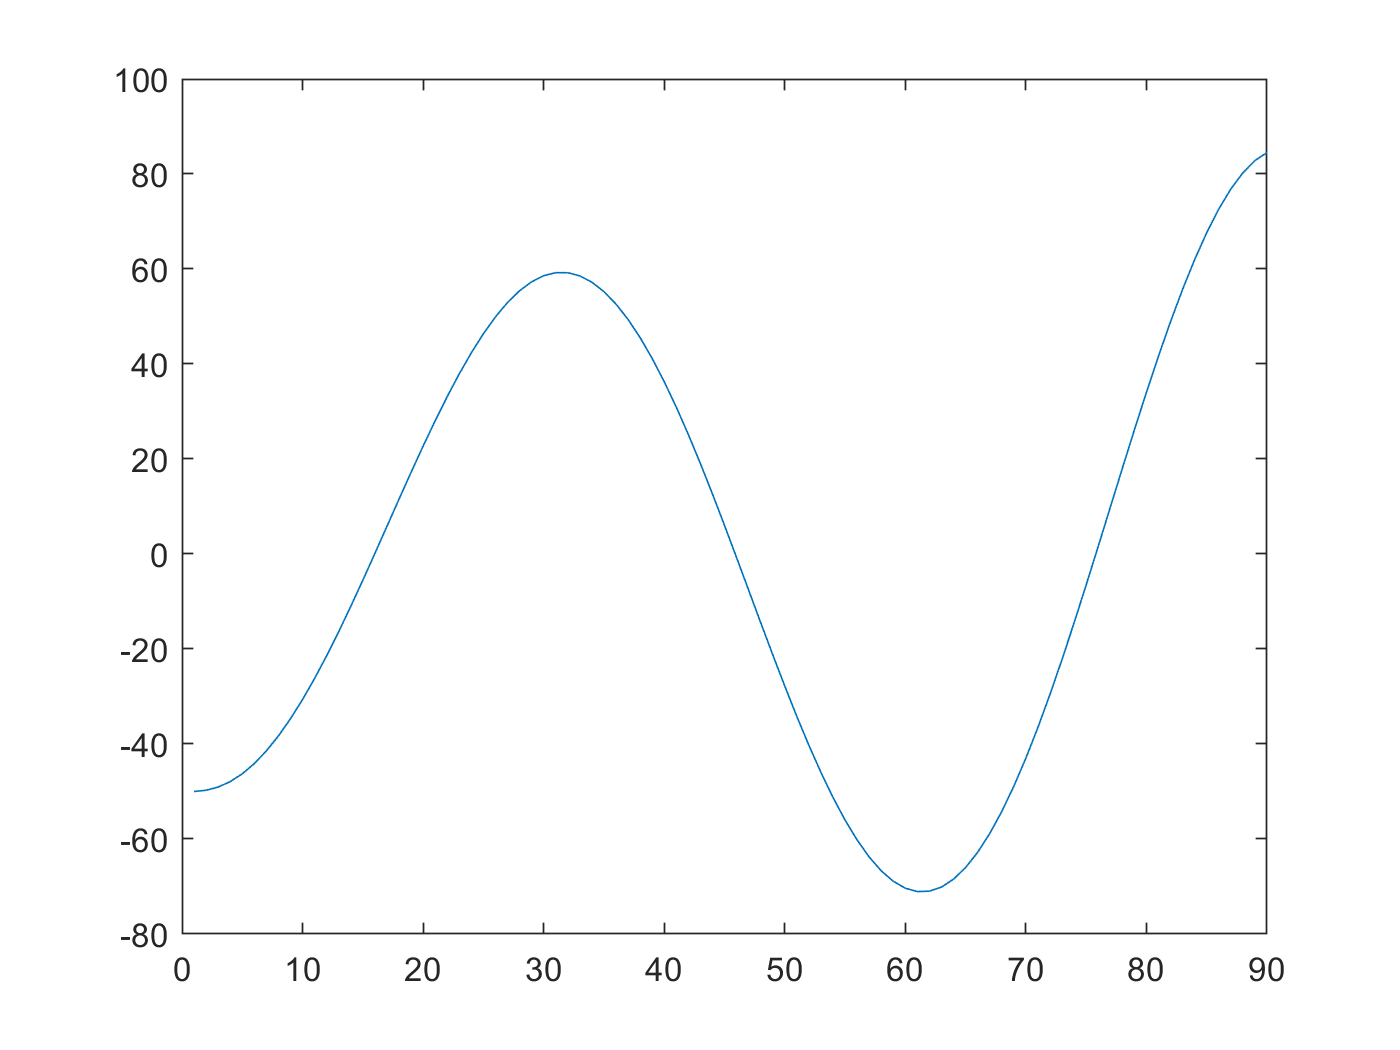


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

%speed_limit = 10;
mu_x = 0.47;
steps = 720;
sum_error = 0;
ki = 0.0053;

x = zeros(1,steps+1);
x(1) = init_x;
speed = 0;

for i = 1:steps
    x_now = x(i);
    error = goal_x - x_now;
    sum_error = sum_error + error;
    power = ki * sum_error;
    actual_power = power - speed*mu_x;
    %speed = min(speed + power, speed);
    speed = speed + actual_power;
    x(i+1) = x_now + speed;
end

plot(1:steps+1, x);
xlim([0 x_size])

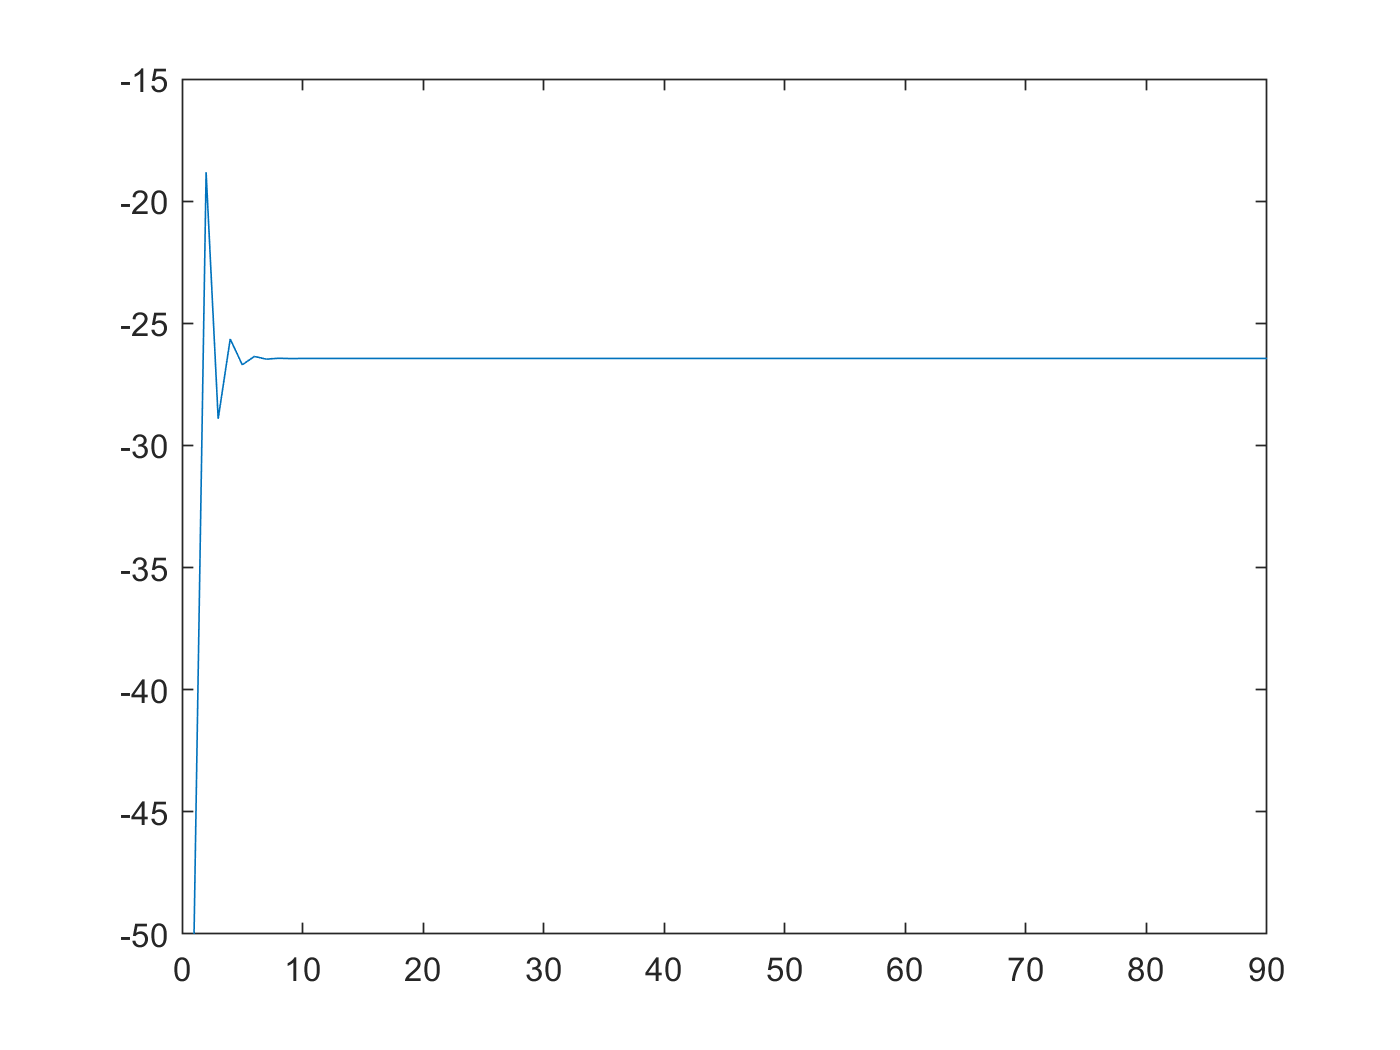



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

%speed_limit = 10;
mu_x = 0.7;
steps = 300;
previous_error = 0;
kd = 1.2474;

x = zeros(1,steps+1);
x(1) = init_x;
speed = 0;

for i = 1:steps
    x_now = x(i);
    error = goal_x - x_now;
    power = kd * (error - previous_error)/2;
    actual_power = power - speed*mu_x;
    %speed = min(speed + power, speed);
    speed = speed + actual_power;
    x(i+1) = x_now + speed;
    previous_error = error;
end

plot(1:steps+1, x);
xlim([0 x_size])